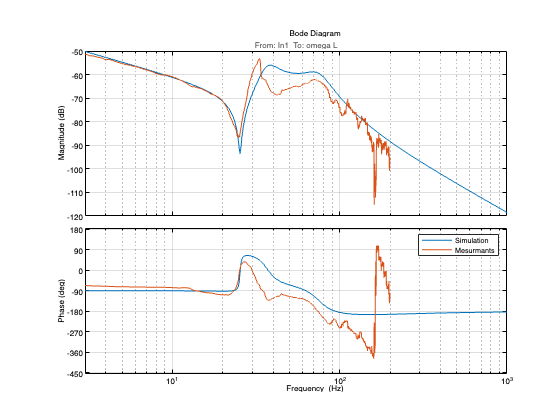

s = tf('s');


JMreg=JMe+JLe/Ne^2+29;
JLreg=JLe+JMe/Ne^2;

J_stareg = (JMreg*JLreg)/(JMreg+JLreg);

Kkeg=JLreg/0.09^2*65;
Kveg=0.0017*Kkeg;

fix_conseg =  0.0042818;

pole_at_zero = fix_conseg/(s);

complex_duble_zero = 1+Kveg*s/Kkeg+JLreg*s^2/Kkeg;

complex_duble_pole = 1+Kveg*s/Kkeg+J_stareg*s^2/Kkeg;

H_M = pole_at_zero*complex_duble_zero/complex_duble_pole;

